Problem 1

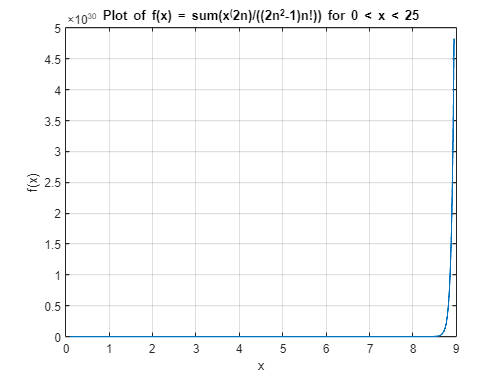

% Define the range and resolution for x values
x_values = linspace(0.1, 25, 1000); % Start from 0.1 to avoid x=0

% Preallocate the f_values array for speed
f_values = zeros(size(x_values));

% Calculate f(x) for each x in the range
for i = 1:length(x_values)
    f_values(i) = problem1Function(x_values(i));
end

% Plot the function
plot(x_values, f_values)
title('Plot of f(x) = sum(x^(2n)/((2n^2-1)n!)) for 0 < x < 25')
xlabel('x')
ylabel('f(x)')
grid on

Problem 2

a)

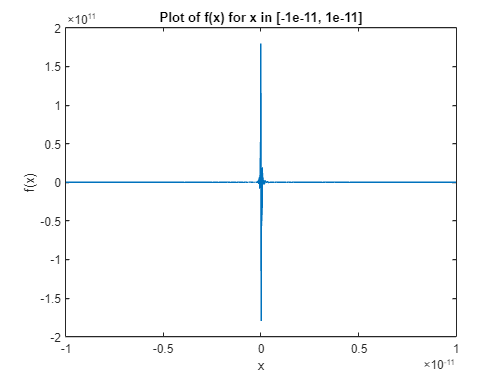

x = linspace(-1e-11, 1e-11, 1000);
f = (exp(x) - 1 - x) ./ x.^2;
plot(x, f)
title('Plot of f(x) for x in [-1e-11, 1e-11]')
xlabel('x')
ylabel('f(x)')

b)

For values of *x* very close to 0, the computation e^x−1-x results in a subtraction of two numbers that are very close to each other, leading to loss of precision. This phenomenon is known as "catastrophic cancellation." Furthermore, dividing by x^2, which is also very close to 0, exacerbates the issue, resulting in a significant relative error.

c) Improved method for computing f for |`x|`<1 and d)

For values of *x* close to 0, we can use the Taylor series expansion of e^x to avoid catastrophic cancellation.

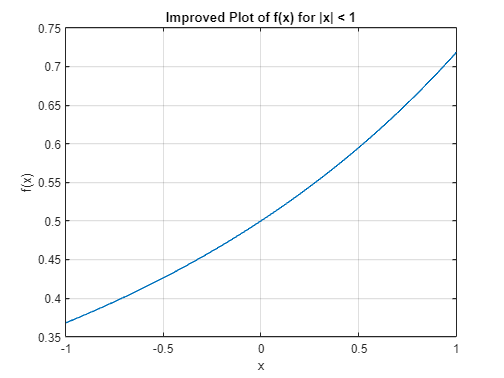

% Define the range of x for |x| < 1
x = linspace(-1, 1, 1000);

% Compute f(x) using the improved function
y = arrayfun(@improvedF, x);

% Plotting
figure;
plot(x, y);
title('Improved Plot of f(x) for |x| < 1');
xlabel('x');
ylabel('f(x)');
grid on;

function f = improvedF(x)
    if abs(x) < 1e-6 % Threshold for using the approximation
        % Use Taylor expansion: e^x = 1 + x + x^2/2! + x^3/3! + ...
        % So, (e^x - 1 - x) / x^2 = 1/2 + x/6 + ...
        f = 1/2 + x/6;
    else
        % Use the direct formula for larger x
        f = (exp(x) - 1 - x) ./ x.^2;
    end
end

function f = problem1Function(x)
    % Initialization
    f = 0; % Initial sum
    term = 1; % First term in the series (n=1)
    n = 1; % Starting index
    
    % Loop until the added term is less than the machine precision
    while term > eps * abs(f)
        term = x^(2*n) / ((2*n^2-1)*factorial(n));
        f = f + term;
        n = n + 1;
        
        % Overflow prevention by checking if term is Inf or NaN
        if isinf(term) || isnan(term)
            break;
        end
    end
end
